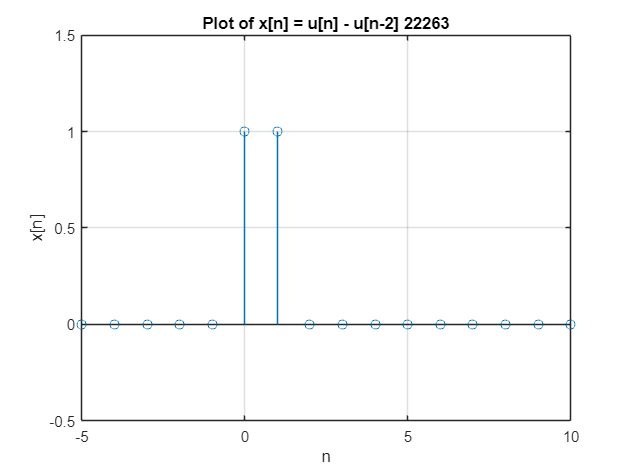

% Define the range for n
n_22263 = -5:10;

% Generate u[n]
u_22263 = n_22263 >= 0;  % This creates a logical array where the condition n >= 0 is true

% Generate u[n-2] by shifting u[n] two places to the right
% For MATLAB indexing, you need to handle the shift manually because MATLAB does not support negative indexing
u_shifted__22263 = [zeros(1, 2), u_22263(1:end-2)];  % Prepend(to add something to the beginning) two zeros for the shift

% Calculate x[n] = u[n] - u[n-2]
x_22263 = u_22263 - u_shifted__22263;

% Plot x[n]
stem(n_22263, x_22263);
xlabel('n');
ylabel('x[n]');
title('Plot of x[n] = u[n] - u[n-2] 22263');
axis([min(n_22263) max(n_22263) -0.5 1.5]); % We can use axis to adjust axis for better visualization
grid on;